cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;addpath('Functions');startup;

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


crossSectionsSet = [0.01;0.02;0.03;0.04;0.05;0.06;0.07;0.08;0.09;0.1]';
ncross = numel(crossSectionsSet);

## Ground structure

### Nodes

nodes.x = [10; 10; 0; 0];                       % x coordinates of nodes
nodes.y = [0; 10; 0; 10];                       % y coordinates of nodes
nodes.z = [0; 0; 0; 0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

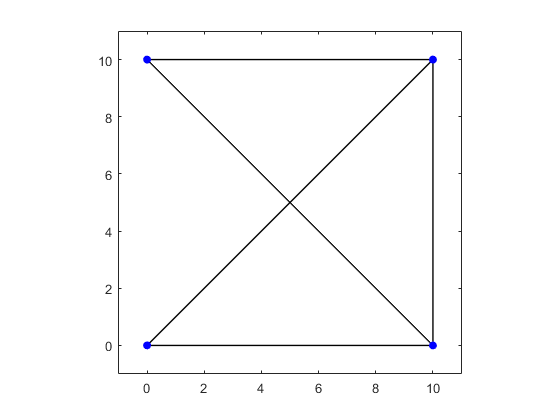

elements.nodes1 = [3; 3; 4; 1; 4];   % elements starting nodes
elements.nodes2 = [1; 2; 1; 2; 2];   % elements ending nodes
nelem = numel(elements.nodes1);  % number of elements  

plot([nodes.x(elements.nodes1) nodes.x(elements.nodes2)]', ...
     [nodes.y(elements.nodes1) nodes.y(elements.nodes2)]', ...
     'k','LineWidth',1);
hold on;
scatter(nodes.x, nodes.y, 'blue', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
hold off;

### Material and cross-section

elements.E = 10^4 ;    % Young moduli of individual elements
elements.Rho = 1 ;    

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [3; 4];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [3; 4];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];      % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [1];             % node indices with x-direction forces
loads.x.value = [5];             % magnitude of the x-direction forces
loads.y.nodes = [1;2];          % node indices with y-direction forces
loads.y.value = [-3;1];          % magnitude of the y-direction forces 
loads.z.nodes = [];             % node indices with z-direction forces
loads.z.value = [];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction

## Optimization parameters

V = 1000;                                  % upper bound for the material volume
minimumCrossSectionArea = 0.01;         % lower bound for cross-section areas. We need it to avoid singular stiffness matrix
maximumStress = 60;
minimumStress = -60;
maximumDisplacement = 15;
minimumDisplacement = -15;


### Design variables

% X = sdpvar(nelem,ncross)
X  = [  0 0 0 0 1 0 0 0 0 0;...
        0 0 0 1 0 0 0 0 0 0;...
        0 0 1 0 0 0 0 0 0 0;...
        0 1 0 0 0 0 0 0 0 0;...
        1 0 0 0 0 0 0 0 0 0 ...
     ]

X =      0     0     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


% S      = sdpvar(nelem,ncross);
S      = [  0 0 0 0 1 0 0 0 0 0;...
            0 0 0 1 0 0 0 0 0 0;...
            0 0 1 0 0 0 0 0 0 0;...
            0 1 0 0 0 0 0 0 0 0;...
            1 0 0 0 0 0 0 0 0 0 ...
         ]*10;
% displacements = sdpvar(nnz(dofs),1);  
U = ones(nnz(dofs),1);
% K = stiffnessMatrixTrussFn()
% todo

### 

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [-deltaX./lengths -deltaY./lengths -deltaZ./lengths deltaX./lengths deltaY./lengths deltaZ./lengths];
matrixB = reshape(cosinus.', 1, []);

## Optimization problem formulation and solution

### Objective function

compliance = 0;
for j = 1:nelem
    for i = 1:ncross
        compliance = compliance + lengths(j) * sum(crossSectionsSet(i)*X(j,i));
    end
end

### Constraints

#### Constraint 1: One area per bar

const1 = sum(X,2) == 1;

#### Constraint 2: Max area per bar

const2 = (0 <= X) & (X <= 1);

#### Constraint 3: Stress constraints

const3 = (X .* crossSectionsSet * minimumStress <= S) & (S <= X .* crossSectionsSet * maximumStress);

#### Constraint 4: Compatibility

Fmin = X .* crossSectionsSet * minimumStress;
Fmax =  X .* crossSectionsSet * maximumStress;
Cmin = kron (elements.E*crossSectionsSet , 1 ./ lengths) .* (sum( matrixB .* (matrixB < 0) .* minimumDisplacement) + sum( matrixB .* (matrixB > 0) .* maximumDisplacement));
Cmax = kron (elements.E*crossSectionsSet , 1 ./ lengths) .* (sum( matrixB .* (matrixB > 0) .* maximumDisplacement) + sum( matrixB .* (matrixB < 0) .* minimumDisplacement));
cmax = (ones(nelem,ncross) - X) .* Cmax;
cmin = (ones(nelem,ncross) - X) .* Cmin;
I = ones(nelem,ncross);

I =      1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


### Objective function

% compliance = endForces'*displacements

### Solution

% ops = sdpsettings('solver','fmincon','verbose',1,'debug',1);
% optimize([nonnegativeCrossSections, volume, equilibriumEquation], ...
%           compliance, ops);

## Post-procesing

### Write solution

% fprintf('Optimized objective: %f\n', value(compliance));
% fprintf('A%d = %f\n', [(1:numel(crossSections))', value(crossSections)]');

### Plotting

Plot the optimal design. Note that the dimensions are scaled.

% nonzeroAreas = value(crossSections)>minimumCrossSectionArea;
% p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
%          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
% set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
% xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
% ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
% zlim([min(nodes.z)-0.1,max(nodes.z)+0.1]);  % To avoid tight limits
% axis equal